# Function for Presentation: TumorDat

A = imageDatastore('Final Project Images\Training\Group1\');
M = datastore('Final Project Images\Training\Group2\');
PT = datastore('Final Project Images\Training\Group3\');

Creates 3 image datastores. We retain the memory from previous fuction to perform calculations on the tumor.

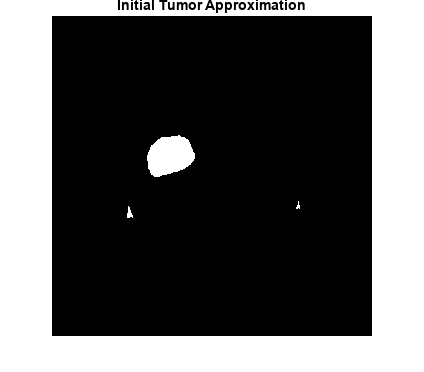

imshow(SkullStripImage);
title('Initial Tumor Approximation')

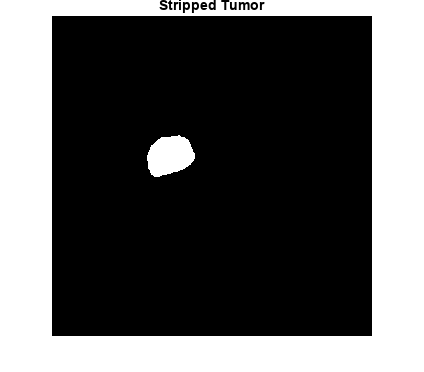

% Initial Tumor Scan from previous function

Label = bwlabel(SkullStripImage);
Description = regionprops(Label, 'Solidity', 'Area');
Area = [Description.Area];
Density = [Description.Solidity];
AverageDensity = mean(Density);
HighestDensity = Density > mad(Density)-0.5;
MaximumArea = max(Area(HighestDensity));
TumorLabel = find(Area == MaximumArea);
Tumor = ismember(Label, TumorLabel);
imshow(Tumor);
title('Stripped Tumor');

display(MaximumArea);

MaximumArea = 3810

display(AverageDensity);

AverageDensity = 0.8833

% Stripped tumor based on region of maxium density.
% It also calculates the area  and average density of the tumor.

Removes any extraneous blobs that are not part of the tumor, resulting in image that is only the tumor. It also calculates the area and density of the tumor.